## Setup for multifrequency reconstruction

% Parameters
kb_s = [1e-3, 1e-2, 1e-1, 1, 10, 100]; % Multifrequency source
L = length(kb_s); % Number of frequencies
lambda = 2*pi / 1; % Assuming kb = 1 (lambda = 2*pi / kb)
rho_s = [lambda/2; 10*lambda]; % Source position

% Object domain D: rectangle from (0,0) to (lambda, lambda)
x_range = [0, lambda];
y_range = [0, lambda];
h = lambda / 20; % Object domain sampling spacing

% Receiver line
M = 50; % Number of receivers
rx = linspace(-lambda, 2*lambda, M);
ry = 1.5 * lambda * ones(size(rx));

% Ground truth object contrast
x = x_range(1):h:x_range(2);
y = y_range(1):h:y_range(2);
[X, Y] = meshgrid(x, y);
% Define a small Gaussian-like object (smooth and low contrast)
radius = 0.25 * lambda;                         % small radius
center = [0.5 * lambda, 0.5 * lambda];          % center of the object
sigma = radius / 2;                             % standard deviation for smooth edges
chi_max = 0.1;                                  % low contrast

% Calculate distance from center
dist2 = (X - center(1)).^2 + (Y - center(2)).^2;

% Smooth Gaussian contrast function
chi = chi_max * exp(-dist2 / (2 * sigma^2));

## Create scattered field at receivers and A matrices for each frequency

stacked_A = [];
stacked_u_sc = [];
for kb = kb_s
    [A, u_sc] = generate_system_matrix(kb, rho_s, x_range, y_range, h, rx, ry, chi);
    stacked_A = [stacked_A ; A];
    stacked_u_sc = [stacked_u_sc ; u_sc];
end

## Reconstruct the constrast

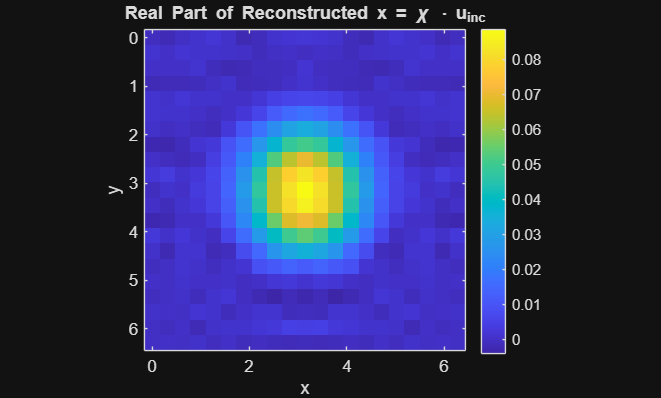

x_est = pinv(stacked_A) * stacked_u_sc;
x_est_image = reshape(x_est, size(X));  % size n×n
figure;
imagesc(x, y, real(x_est_image));
axis equal tight;
colorbar;
xlabel('x'); ylabel('y');
set(gca, 'YDir', 'reverse');
title('Real Part of Reconstructed x = \chi \cdot u_{inc}');